# Noise Variances

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
Initializing global node /matlab_global_node_01926 with NodeURI http://sml-OptiPlex-9010:42969/ and MasterURI http://localhost:11311.
  callback_class with properties:

     message: 'nav_msgs/Odometry'
    meas_pos: [0 0 0]



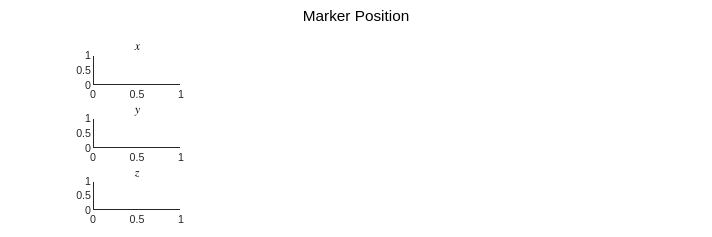

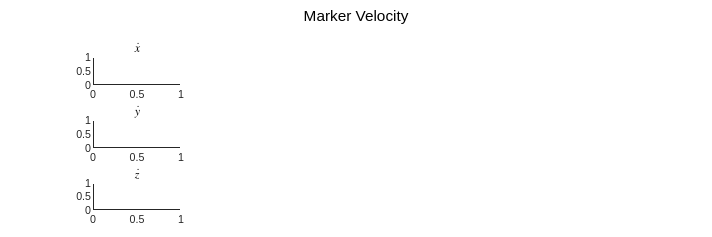

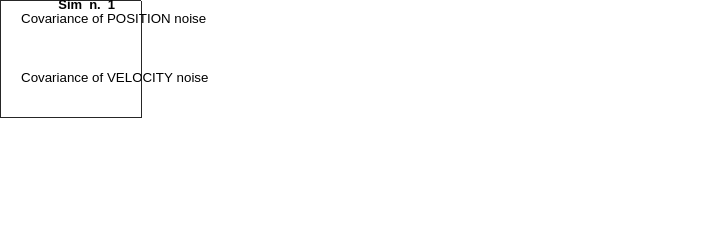

Index exceeds the number of array elements. Index must not exceed 0.

Error in Noise_estimation (line 114)
        if (meas_pos(1) < 0)

Error in run (line 91)
evalin('caller', strcat(script, ';'));

% Run script
run('Noise_estimation.m');

# Mex functions generation

#### FORWARD KINEMATICS


$$\pmatrix{p_{1} \cr P_{2} \cr .. \cr P_{M}} = \pmatrix{\Phi_1(q) \cr \Phi_2(q) \cr ..  \cr \Phi_M(q) } \qquad \Longrightarrow \qquad  p = \Phi(q)$$


#### JACOBIAN COMPUTATION


$$\pmatrix{\dot{p}_{1} \cr \dot{p}_{2} \cr .. \cr \dot{p}_{M}} = \pmatrix{J_1(q) \cr J_2(q) \cr ..  \cr J_M(q) } \cdot \dot{q} \qquad \Longrightarrow \qquad  \tilde{u} = J(q) \cdot  \dot{q} $$


% Clear variables
clear;
clear global;
close all;
clc;

% Run trajectory
load('q_trajectory.mat');

% Run human_arm_parameters
run('human_arm_parameters.m');

% Run script
mex_generation(arm.markers.links, sample_Time, 'false');

% See if any singularities are present
max_number_simulations = 1000;
singular_config(q_trajectory, shoulder_num, forearm_num, hand_num, 1e-10, max_number_simulations);

# LS APPROACH


$$\dot{q} = J^{\dagger}(q) \cdot  \tilde{u} \qquad \longrightarrow \qquad \tilde{u} = \dot{p}$$


% Clear variables
clear;
close all;
clc;

% Run trajectory
load('q_trajectory.mat');

% Human arm parameters
run('human_arm_parameters.m');

## 1.  PERFECT GUESS OF INITIAL CONDITION q0 

% Model IC 
q0_model = q_trajectory.signals.values(1, :)';

% LS IC
q0_LS = q0_model;

% Results
LS_KF_EKF_NLDM("LS", 'precomputed', [], directory);

## 2.  WRONG GUESS OF INITIAL CONDITION q0 

% Model IC 
q0_model = q_trajectory.signals.values(1, :)';

% LS IC
q0_LS = zeros(n, 1);

% Results
LS_KF_EKF_NLDM("LS", 'precomputed', [], directory);

# KALMAN FILTER ON LINEARIZED DISCRETE STATE-SPACE MODEL

## 1.  Discrete Non Linear model (Ts = 10ms)

Runge-Kutta discretization method is applied to the continuos NL model. The sampling time Ts = 10ms was chosen.


$$\begin{cases}
\mathbf{q}_{k+1} = \textbf{f}(\mathbf{q}_k, \mathbf{\tilde{u}}_k)   \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) 
+  \mathbf{v}_k \\
\end{cases} \qquad , \quad 

\begin{cases}
\mathbf{\tilde{u}}_k \sim \mathcal{N}(0, \mathbf{N_u})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases} \\
\textbf{f} = \mathbf{q}_k + \frac{1}{6}  \cdot T_s  \cdot (\mathbf{k_1} + 2\mathbf{k_2} + 2\mathbf{k_3} + \mathbf{k_4})
\\
\\
\mathbf{k_1} = \mathbf{J}^{\dagger}(\mathbf{q}_k)\cdot \mathbf{\tilde{u}}_k  \\
\mathbf{k_2} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  \frac{k_1}{2})\cdot \mathbf{\tilde{u}}_k  \\
\mathbf{k_3} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  \frac{k_2}{2})\cdot \mathbf{\tilde{u}_k  \\
\mathbf{k_4} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  k_3)\cdot \mathbf{\tilde{u}}_k$$


The comparison between the simulation and the discrete Non Linear model is reported below.

% Clear variables
clear;
close all;
clc;

% Run trajectory
load('q_trajectory.mat');

% Human arm parameters
run('human_arm_parameters.m');

% Model IC 
q0_model = q_trajectory.signals.values(1, :)';

% Sample time is fixed at 0.01
LS_KF_EKF_NLDM("NLDM", 'precomputed', [], directory);

## 2.  Linearized Discrete model around equilibrium point

The Discrete state-space model is computed by linearizing the discrete NL model around a given equilibrium point.                                                


$$\begin{cases}
\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot \mathbf{\Delta \tilde{u}}_k  + \mathbf{w}_k \\
\mathbf{\Delta p}_k = \mathbf{H}\cdot\mathbf{\Delta q}_k  + \mathbf{v}_k\\
\end{cases} \qquad , \quad 
\begin{cases}
\mathbf{\Delta q}_{k} = \mathbf{q}_k - \mathbf{q}_{eq} \\
\mathbf{\Delta \tilde{u}}_{k} = \mathbf{\tilde{u}}_k - \mathbf{u}_{eq} \\
\mathbf{\tilde{u}}_k = \mathbf{\bar{u}}_k + \mathbf{n}_k
\end{cases} \qquad , \quad \begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


where,


$$\\
\mathbf{F} = \nabla_q\textbf{f}|_{q_{eq}, u_{eq}} \\
\mathbf{G} = \nabla_u\textbf{f}|_{q_{eq}, u_{eq}} \\
\mathbf{H} = \nabla_q\mathbf{\Phi}|_{q_{eq}}$$


## 3.  Kalman Filter on the linearized discrete state-space model

The Discrete state-space model is computed by linearizing the discrete NL model around the given equilibrium point.                                              


$$\begin{cases}
\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot \mathbf{\Delta \tilde{u}}_k  + \mathbf{w}_k \\
\mathbf{\Delta p}_k = \mathbf{H}\cdot\mathbf{\Delta q}_k  + \mathbf{v}_k\\
\end{cases} \qquad , \quad \begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


In simulink, the above state space representaion was implemented. Th considered input was  $\mathbf{\Delta \tilde{u}}_k + \mathbf{n}_k$, so that $\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot (\mathbf{\Delta \tilde{u}}_k  + \mathbf{n}_k)$,            $\mathbf{n}_k \sim \mathcal{N}(0, \mathbf{N})$

The matrix $\mathbf{N}$ was computed such that $\mathbf{GNG^T} = \mathbf{Q}$

% Clear variables
clear;
close all;
clc;

% Run trajectory
load('q_trajectory.mat');

% Human arm parameters
run('human_arm_parameters.m');

% Model IC 
q0_model = q_trajectory.signals.values(1, :)';

% Equilibrium point
kf.q_eq = zeros(n, 1);
kf.u_eq = zeros(3*m, 1);

% Initial estimate Delta_q0
kf.Delta_q0 = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 0.1 * eye(n);

% Results
LS_KF_EKF_NLDM("KF", 'precomputed', number_samples, directory);

### 3.2 Free arm motion

The discrete NL model is now linearized around the rest position of the human arm, i.e. when the human arm is perpendicular to the ground.

In this context all initial joints' variables are assumed to be set to 0°.


$$q_0 = \pmatrix{0\degree  \cr 0\degree  \cr ..  \cr 0\degree } , \qquad q_{eq} =  \pmatrix{0 \degree  \cr 0\degree  \cr ..  \cr 0\degree },  \qquad u_{eq} =  \pmatrix{ 0  \cr 0  \cr ..  \cr 0 } $$


The comparison between simulation and linearized discrete state-space is reported below.

% Model IC
q0_model = zeros(n, 1);

% Equilibrium point
kf.q_eq = zeros(n, 1);
kf.u_eq = zeros(3*m, 1);

% Initial estimate Delta_q0
kf.Delta_q0 = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 10 * eye(n);

% Results
LS_KF_EKF_NLDM("KF", 'free', number_samples, directory);

# EXTENDED KALMAN FILTER

## 1.  Discrete Non Linear model


$$\begin{cases}
\mathbf{q}_{k} = \textbf{f}(\mathbf{q}_{k-1}, \mathbf{u}_{k-1}) + \mathbf{w}_{k-1}  \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) + \mathbf{v}_k \\
\end{cases}  \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


We perform a Taylor series expansion of the state equation around $\mathbf{q}_{k-1} = \hat{\mathbf{q}}_{k-1}^+$ and we obtain:


$$\mathbf{q}_{k} = \mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^+, \mathbf{u}_{k-1}\right) + \left.\frac{\partial \mathbf{f}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}}\left(\mathbf{q}_{k-1}-\hat{\mathbf{q}}_{k-1}^{+}\right) + \mathbf{w}_{k-1} \\ =
\mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}\right)+\mathbf{F}_{k-1}\left(\mathbf{q}_{k-1}-\hat{\mathbf{q}}_{k-1}^{+}\right) + \mathbf{w}_{k-1} \\ =

\mathbf{F}_{k-1} \mathbf{q}_{k-1}+\left[\mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}\right)-\mathbf{F}_{k-1} \hat{\mathbf{q}}_{k-1}^{+}\right] + \mathbf{w}_{k-1} \\ =
\mathbf{F}_{k-1} \mathbf{q}_{k-1}+\mathbf{r}_{k-1}+\mathbf{w}_{k-1}$$


We linearize the measurement equation around $\mathbf{q}_k = \hat{\mathbf{q}}_k^-$ and we obtain:


$$\mathbf{p}_{k} = \mathbf{\Phi}\left(\hat{\mathbf{q}}_k^-\right) + \left.\frac{\partial \mathbf{\Phi}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k}^{-}}\left(\mathbf{q}_{k}-\hat{\mathbf{q}}_{k}^{-}\right)+ \mathbf{v}_{k} \\ =

\mathbf{\Phi}\left(\hat{\mathbf{q}}_k^-\right) + \mathbf{H}_{k}\left(\mathbf{q}_{k}-\hat{\mathbf{q}}_{k}^{-}\right)+ \mathbf{v}_{k} \\ =

\mathbf{H}_{k}\mathbf{q}_{k}+\left[\mathbf{\Phi}\left(\hat{\mathbf{q}}_{k}^{-}\right)-\mathbf{H}_{k}\hat{\mathbf{q}}_{k}^{-}\right]+\mathbf{v}_k \\ =
\mathbf{H}_{k} \mathbf{q}_{k}+\mathbf{z}_{k}+\mathbf{v}_{k}$$
				

We can use the standard Kalman Filter equations to estimate the state.

In summary, the following steps are performed to compute the KF estimate at each step.

- The system and measurement equations are given as follows 

          
$$\begin{cases}
\mathbf{q}_{k} = \textbf{f}(\mathbf{q}_{k-1}, \mathbf{u}_{k-1}) + \mathbf{w}_{k-1}  \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) + \mathbf{v}_k \\
\end{cases}  \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


- Initialize the filter as follows  $\hat{\mathbf{q}}_{0}^+ = \mathbb{E}(\mathbf{q}_0) \quad, \quad
\mathbf{P}_0^+ = \mathbb{E}[(\mathbf{q}_0 - \hat{\mathbf{q}}_{0}^+)(\mathbf{q}_0 - \hat{\mathbf{q}}_{0}^+)^T]$ 

- For k = 1, 2, .. perform the following 

                          
$$\mathbf{F}_{k-1} =  \left.\frac{\partial \mathbf{f}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k-1}^{+},\mathbf{u}_{k-1}
$$


                            **TIME UPDATE**

                            
$$\mathbf{P}_k^- = \mathbf{F}_{k-1}\mathbf{P}_{k-1}^+\mathbf{F}_{k-1}^T + \mathbf{Q} \\
\hat{\mathbf{q}}_k^- = \mathbf{f}(\hat{\mathbf{q}}_{k-1}^+, \mathbf{u}_{k-1})$$


                             
$$\mathbf{H}_{k} =  \left.\frac{\partial \mathbf{\Phi}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k}^{-}$$


                            **MEASUREMENT UPDATE**

                            
$$\mathbf{K}_k = \mathbf{P}_{k}^-\mathbf{H}_{k}^T(\mathbf{H}_k\mathbf{P}_k^-\mathbf{H}_k^T + \mathbf{R})^{-1}
\\
\hat{\mathbf{q}}_k^+ = \hat{\mathbf{q}}_k^- + \mathbf{K}_k[\textbf{p}_k - \mathbf{\Phi}(\hat{\mathbf{q}}_k^-)]
\\
\mathbf{P}_k^+ = (\mathbf{I} - \mathbf{K}_k\mathbf{H}_k)\mathbf{P}_k^-$$


A new example is now considered.

% Clear variables
clear;
close all;
clc;

% Run trajectory
load('q_trajectory.mat');

% Human arm parameters
run('human_arm_parameters.m');

% Model IC 
q0_model = q_trajectory.signals.values(1, :)';

% Initial estimate q0
ekf.q0 = q0_model;

% Initial covariance estimate P0
ekf.P0 = diag([0.001*ones(3,1); 4; 0.001*ones(3,1)]);

% Results
LS_KF_EKF_NLDM("EKF", 'precomputed', number_samples, directory);

# Comparison between Methods

% Clear variables
clear;
close all;
clc;

% Run trajectory
load('q_trajectory.mat');

% Human arm parameters
run('human_arm_parameters.m');

% Model IC 
q0_model = q_trajectory.signals.values(1, :)';

## LS

% LS IC
q0_LS = q0_model;

## KF

% Equilibrium point
kf.q_eq = zeros(n, 1);
kf.u_eq = zeros(3*m, 1);

% Initial estimate Delta_q0
kf.Delta_q0 = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 1 * eye(n);

## EKF

% Initial estimate q0
ekf.q0 = q0_model;

% Initial covariance estimate P0
ekf.P0 = diag([0.002 * ones(n, 1)]);


## Results

LS_KF_EKF_NLDM(["LS", "EKF"], 'precomputed', number_samples, directory);